# Problem 1

Part b

s = tf('s');
G = (-s+10) / ((s+1)*(s+100));

[mag, phase, w] = bode(G);
mag = squeeze(mag);
phase = squeeze(phase);

w_u = interp1(phase, w, 180)

w_u = 33.3941

p_u = 2*pi() / w_u

p_u = 0.1882

K_u = 1 / interp1(w, mag, w_u)

K_u = 100.9979

K = K_u / 2.2 * (1 + 1 / ((p_u/1.2)*s))

K =
 
  7.198 s + 45.91
  ---------------
     0.1568 s
 
Continuous-time transfer function.
Model Properties


Part c

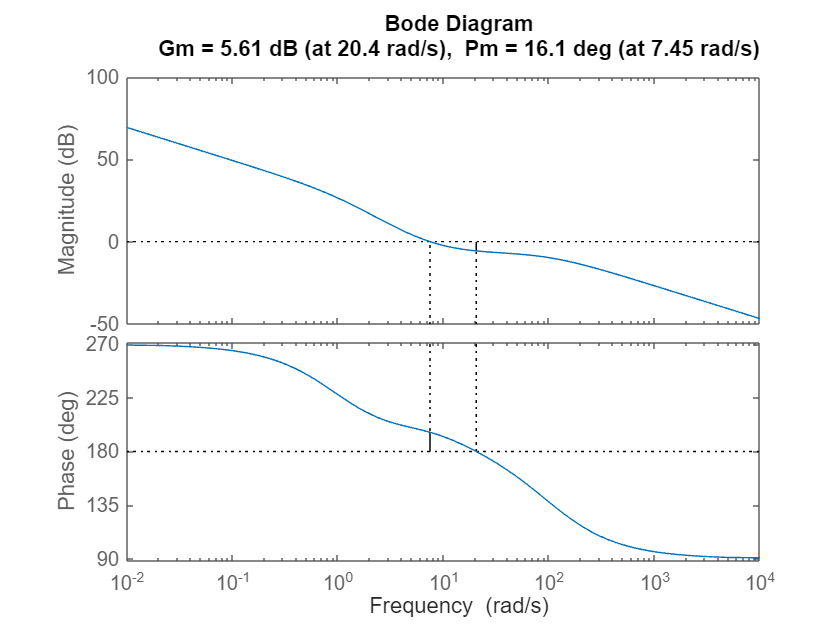

margin(K*G)

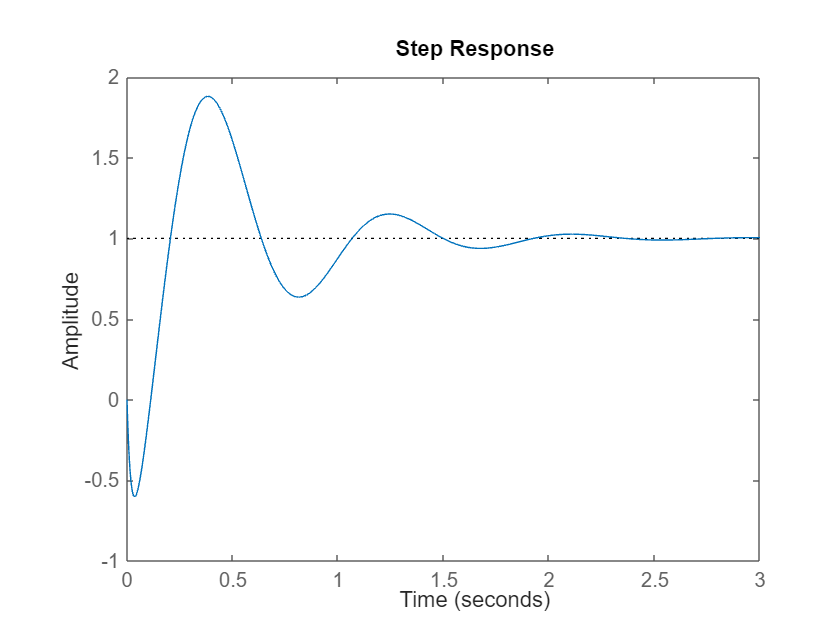

step(feedback(K*G, 1))

Part d

G2 = (s-10)/((s+1)*(s+100));
C = pid(1,1,0,0);
isstable(feedback(C*G2, 1))

ans = logical
   0


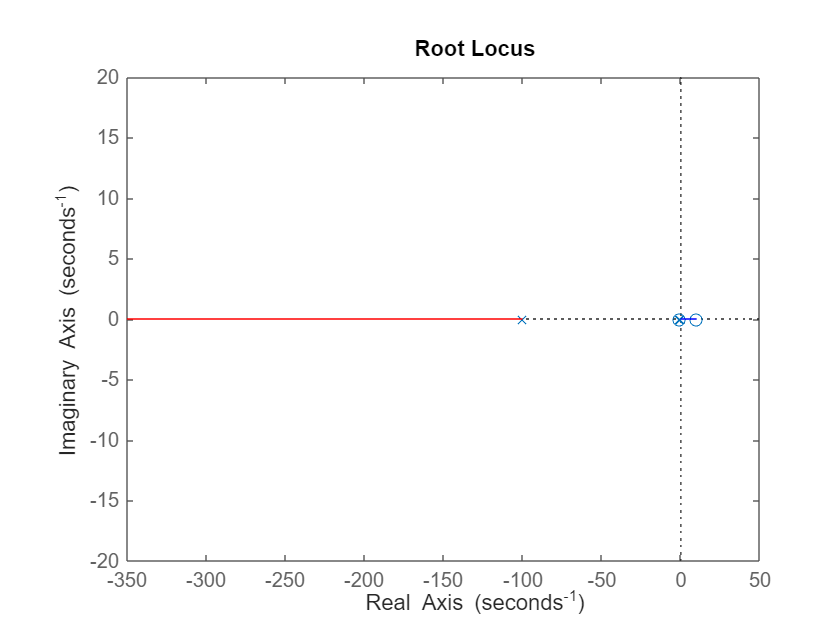

rlocus(C*G2)

No matter what coefficients or gain are chosen, there will always be a RHP pole. Thus, the system is never stabilizable with PI.

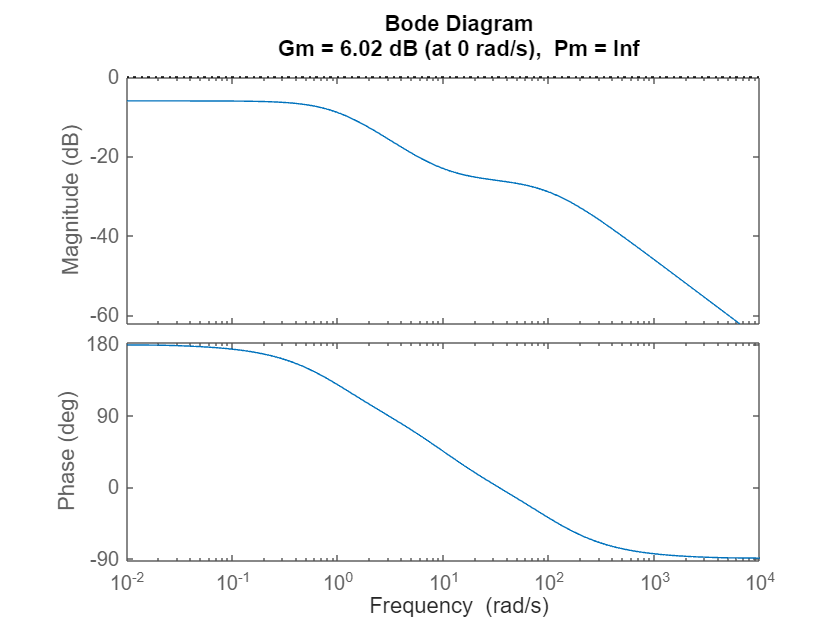

C2 = pid(5,0,0,0);
margin(C2*G2)

isstable(feedback(C2*G2, 1))

ans = logical
   1


# Problem 2

Part a

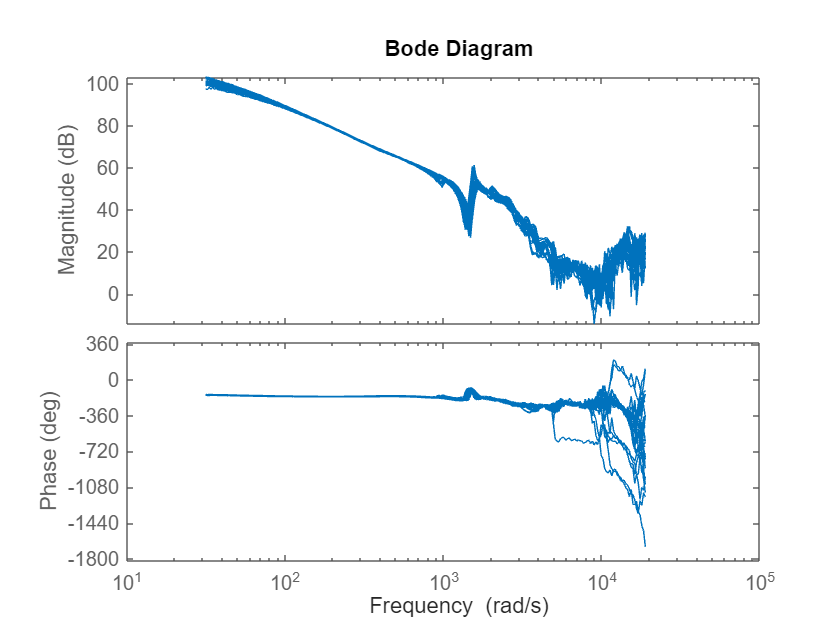

data = load('respdata.mat');
sys = data.sys;
s = tf('s');
bode(sys)

gmd = db2mag(6);
pmd = 40;

wh = 1200;
wl = 600;
w_try = wh;
w_new = 1/2*(wh+wl);
s = tf('s');
% Notch the resonance peak
N = notch(15, 300, 1600);
while(abs(w_new-w_try)>.001)
    w_try = w_new;

    % PI Compensator
    C = (s + w_try/10) / s;

    % Get phase at crossover for system with lowest phase at crossover
    min_phase = 1000;
    for i=1:27
        [mag, phase] = bode(sys(:,:,i,1)*N*C, w_try);
        if phase < min_phase
            min_phase = phase;
        end
    end

    % Calculate phase lead and make compensator
    Plead = (pmd - 180) - min_phase;
    Clead = lead(Plead,w_try);

    % Get magnitude at crossover and adjust crossover to have magnitude of
    % 1 for worst case
    max_mag = 0;
    for i=1:27
        [mag,phase] = bode(sys(:,:,i,1)*N*C*Clead, w_try);
        if mag > max_mag
            max_mag = mag;
        end
    end
    K = 1/max_mag;

    % Get GM and PM
    [Gm,Pm,Wcg,Wcp] = margin(K*sys*N*C*Clead);
    if all(Gm>gmd)
        wl = w_try;
    else
        wh = w_try;
    end
    w_new = 1/2*(wh+wl);
end

[Gm,Pm,Wcg,Wcp] = margin(K*sys*N*C*Clead);
all(Gm > gmd)

ans = logical
   1


all(Pm > pmd)

ans = logical
   1


Part b

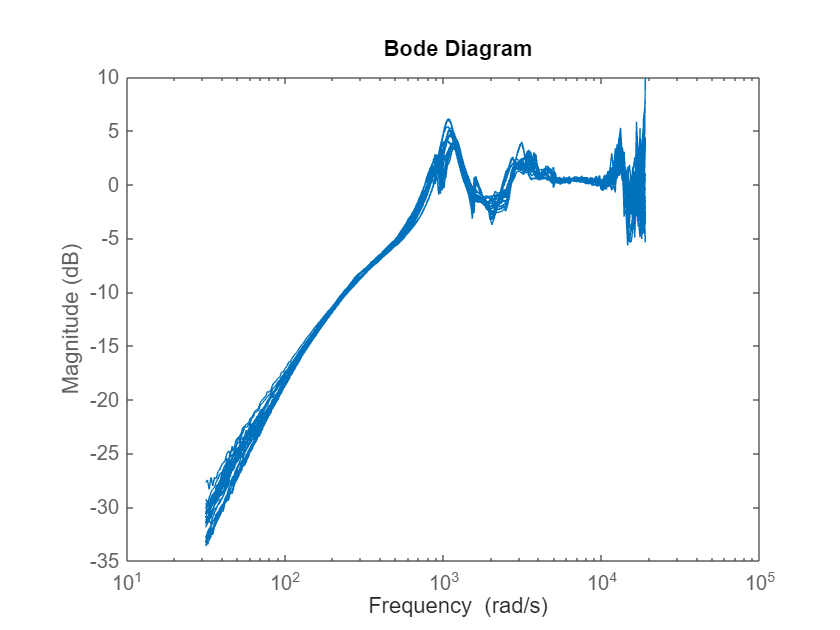

sensitivity = 1 - feedback(K*sys*N*C*Clead, 1);
bodemag(sensitivity)

Peak value is roughly 6 dB at the first peak, though there are some higher peaks at high frequency.

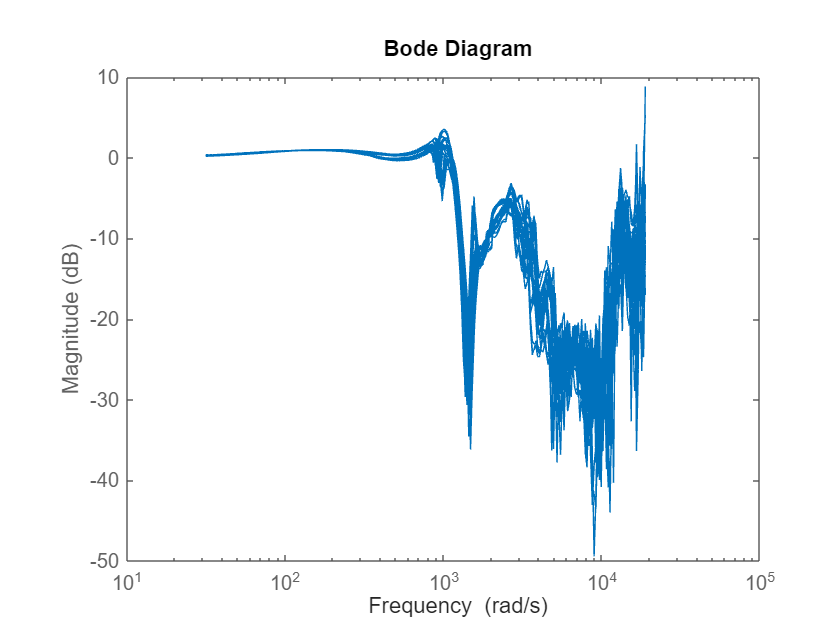

bodemag(1 - sensitivity)

Peak value is around 4 dB at the first peak, but there are some higher peaks at high frequency.

Part c

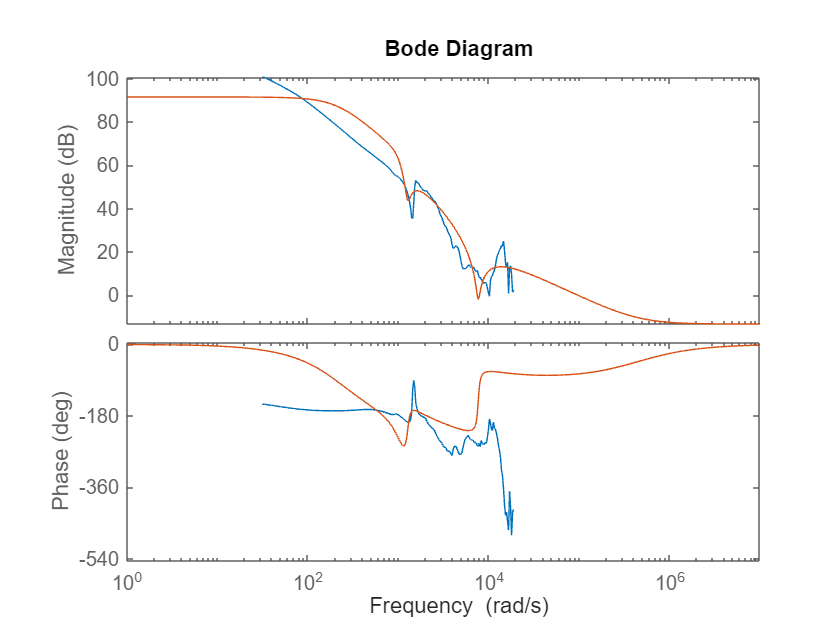

responses = [];
for i=1:27
    responses = [responses, sys(:,:,i,1).Response];
end
avg_response = mean(responses, 2);
avg = frd(avg_response, sys(:,:,1,1).Frequency);
approx = fitmagfrd(avg, 5);
bode(avg, approx)

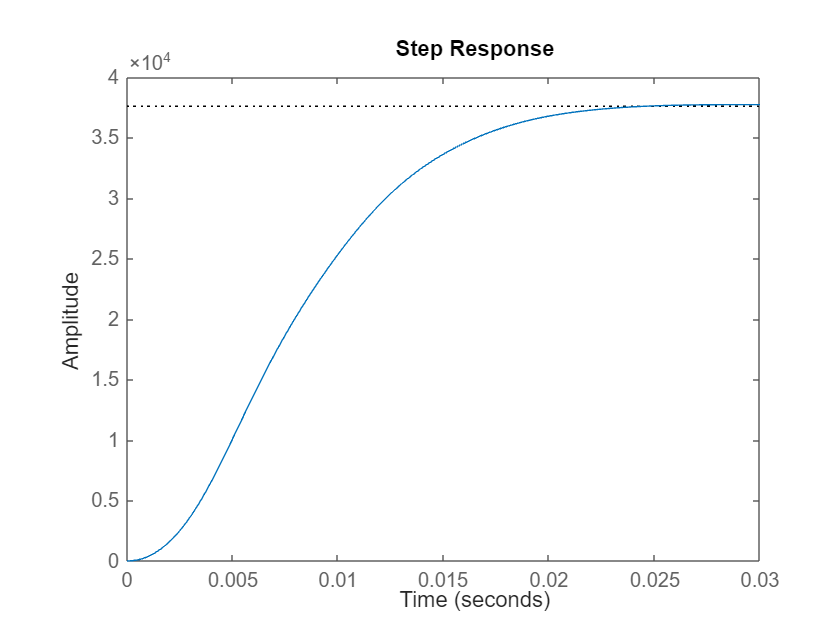

step(approx)